# Inverse kinematics

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

*TODO VARIOUS ROBOTS: 2 LINK, HYPER2D, HYPER3D*

Inverse kinematics is the problem of finding the robot joint coordinates, given a homogeneous transform representing the last link of the manipulator. It is very useful when the path is planned in Cartesian space, for instance  a straight line path as shown in the trajectory demonstration.

First generate the transform corresponding to a particular joint coordinate, `q`, using forward kinematics

mdl_puma560
q = [0 -pi/4 -pi/4 0 pi/8 0]

q =          0   -0.7854   -0.7854         0    0.3927         0


T = p560.fkine(q)

 

T = 
    0.3827         0    0.9239    0.7371
         0         1         0   -0.1501
   -0.9239         0    0.3827   -0.3256
         0         0         0         1


Now the inverse kinematic procedure for any specific robot can be derived symbolically and in general an efficient closed-form solution can be  obtained.  However we are given only a generalized description of the  manipulator in terms of kinematic parameters so an iterative solution will  be used. The procedure is slow, and the choice of starting value affects  search time and the solution found, since in general a manipulator may  have several poses which result in the same transform for the last link. The starting point for the first point may be specified, or else it defaults to zero (which is not a particularly good choice in this case)

qi = p560.ikine(T);


 and the result

qi

qi =     0.0000   -0.7854   -0.7854    0.0000    0.3927   -0.0000


is the same as the original set of joint angles

q

q =          0   -0.7854   -0.7854         0    0.3927         0


However in general this will not be the case, there are multiple solutions, and the solution that is found depends on the initial choice of angles.

A more efficient approach is to use an analytic solution and the toolbox  supports the common case of a 6-axis robot arm with a spherical wrist


qi = p560.ikine6s(T)

qi =     2.7400   -3.0950   -0.7854    2.7547    1.2768    0.2787


which is different to the original joint angles, but the forward kinematics shows that these angles give the same end-effector pose

p560.fkine(qi)

 

ans = 
    0.3827         0    0.9239    0.7371
         0         1         0     -0.15
   -0.9239         0    0.3827   -0.3256
         0         0         0         1


The analytic solution allows the specific solution to be specified using a character string and to get the same set of joint angles


p560.ikine6s(T, 'rdf')

ans =    -0.0000   -0.7854   -0.7854    3.1416   -0.3927   -3.1416


where we have specified that the robot is in a right-handed configuration (r), with its elbow down (d), and the wrist flipped (f).

 A solution is not always possible, for instance if the specified  transform describes a point out of reach of the manipulator.  As  mentioned above the solutions are not necessarily unique, and there  are singularities at which the manipulator loses degrees of freedom  and joint coordinates become linearly dependent.

## Trajectory

Inverse kinematics may also be computed for a trajectory. If we take a Cartesian straight line path between two poses in 50 steps


T1 = transl(0.6, -0.5, 0.0) % define the start point

T1 =     1.0000         0         0    0.6000
         0    1.0000         0   -0.5000
         0         0    1.0000         0
         0         0         0    1.0000


T2 = transl(0.4, 0.5, 0.2)	% and destination

T2 =     1.0000         0         0    0.4000
         0    1.0000         0    0.5000
         0         0    1.0000    0.2000
         0         0         0    1.0000


T = ctraj(T1, T2, 50); 	% compute a Cartesian path


now solve the inverse kinematics

q = p560.ikine6s(T); 
about q

q [double] : 50x6 (2.4 kB)


which has one row per time step and one column per joint angle

Let's examine the joint space trajectory that results in straight line Cartesian motion

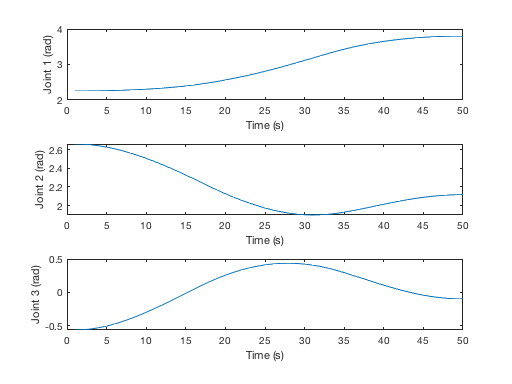


subplot(3,1,1); plot(q(:,1)); xlabel('Time (s)'); ylabel('Joint 1 (rad)');
subplot(3,1,2); plot(q(:,2)); xlabel('Time (s)'); ylabel('Joint 2 (rad)');
subplot(3,1,3); plot(q(:,3)); xlabel('Time (s)'); ylabel('Joint 3 (rad)');

This joint space trajectory can now be animated

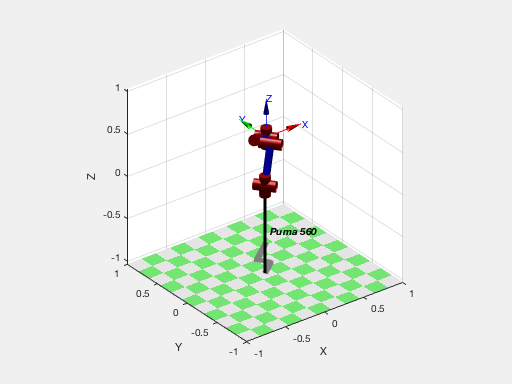

clf; p560.plot(q)